# parameter setting of a rimless wheel

运行前请确定RLW的所有文件在当前运行的目录！！！

close all;  
clc;

% Specifies the number of spokes
Nspk = 10;       % number of the spoke(5~10)
Nwt = 4;        % number of additional weight(2,4,6)

% 基础的RimlessWheel的所有参数，
par.M = 1.034;          % gram
par.I = 0.0030452;      % meter.m^2  (inertia) （基础8辐的RimlessWheel）
par.L = 0.11;           % meter （The length of the spoke）
par.Phi = 2*pi/Nspk;    % radian (The Angle between the spokes)
par.g = 9.8;            % meter/sec^2 (gravity acceleration)
slopeAngle = 60;
par.Gamma = -pi/slopeAngle;     % radian (angle of the slope)

% 配重
Wt.M = 0.18*Nwt;
Wt.I = 0.00002503*Nwt;

% 给基础RimlessWheel增加配重,得到最终的机器人
par.M = par.M + Wt.M;
par.I = par.I + Wt.I;

## find a fixed point

close all;  
clc;

% Guess an initial state
s0 = [ par.Phi/2-par.Gamma; -pi/1.25];    %[angle; angluar velocity]
t0 = 0;

% Options for fsolve
options = optimset('TolFun',1e-12,'TolX',1e-12,'LargeScale','off','MaxFunEvals',20); 

% find a fixed point
s_fp = fsolve(@(s) Step(s,0,par)-s,s0,options)

STEP: Inproper State. S0(1) is changed to the Maxium value Phi/2
STEP: Inproper State. S0(1) is changed to the Maxium value Phi/2
STEP: Inproper State. S0(1) is changed to the Maxium value Phi/2

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，
问题似乎为正则问题。

<停止条件详细信息>


s_fp =     0.3142
   -3.3826


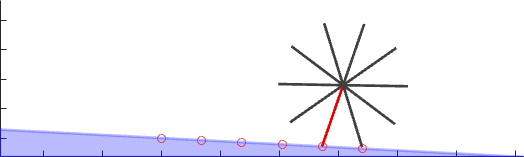

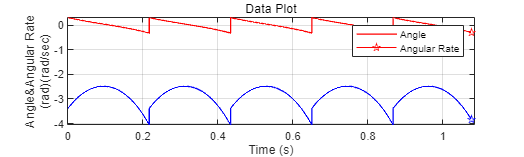

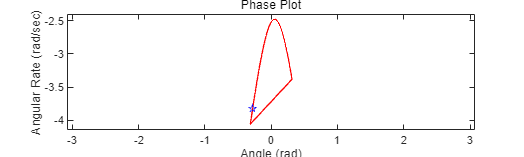


% walk 5 steps with s_fp as the initial state
% data store all informations during the walking, in order to animate it later 
[s_end, t_end, data] = Walk(s_fp, t0, par,5);

% animate the walking
Animation(data, par, 2);

## walking 20 steps with a specified inial state

close all;
clc;

% Speicify an initial states
theta0 = par.Phi/2-par.Gamma;
theta_d0 = -sqrt( 2*par.M*par.g*par.L*(1-cos(par.Phi/2+par.Gamma) )/(par.M*par.L^2+2*par.I) );

s0 = [theta0; theta_d0];
t0 = 0;

% Take 10 steps. 
[s_end, t_end, data] = Walk(s0, t0, par,20);

STEP: Inproper State. S0(1) is changed to the Maxium value Phi/2


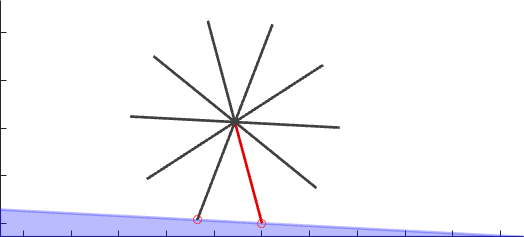

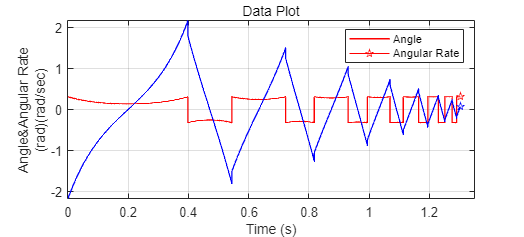

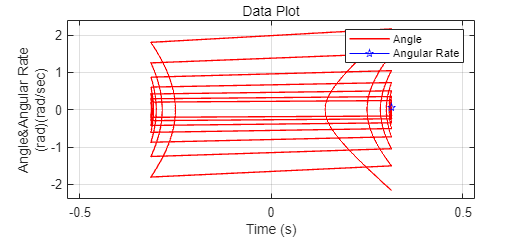

Animation(data, par, 2);

% 这个例子是一个初始速度过小，能量不足的情况，因此形成不了极限环。

## walking 20 steps with another specified inial state

close all;
clc;

% Initial Conditions
s0 = [0; -3];
t0 = 0;

% Take 10 steps. 
[s_end, t_end, data] = Walk(s0, t0, par,30);
disp(is_limit_cycle(data))

     1



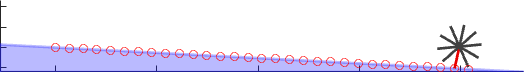

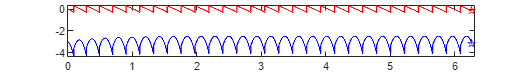

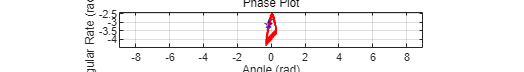

Animation(data, par, 2);

% 这个例子是初始速度较大，但最终能收敛到稳定极限环的情况。
% 对于8个辐的RimlessWheel，初速度是足够大的，
% 但对于7个辐的RimlessWheel，初速度仍较小，仍需要加大。

## Try to draw BOA

定义状态空间范围

% 定义状态空间范围
theta_range = linspace(-par.Phi/2, par.Phi/2, 50);  % 角度范围
omega_range = linspace(-pi, 0, 50);  % 角速度范围

% 初始化吸引盆地图
basin = zeros(length(theta_range), length(omega_range));

% 循环遍历所有初始状态
for i = 1:length(theta_range)
    for j = 1:length(omega_range)
        % 获取初始状态
        theta0 = theta_range(i);
        omega0 = omega_range(j);
        
        % 进行模拟
        [s_end, t_end, data] = Walk([theta0; omega0], 0, par, 30);
        
        % 判断吸引子
        basin(i, j) = is_limit_cycle(data);
    end
end

STEP: Time is up. Increase max_time in Step.m
STEP: Time is up. Increase max_time in Step.m
STEP: Time is up. Increase max_time in Step.m
STEP: Time is up. Increase max_time in Step.m
STEP: Time is up. Increase max_time in Step.m
STEP: Time is up. Increase max_time in Step.m
STEP: Time is up. Increase max_time in Step.m
STEP: Time is up. Increase max_time in Step.m
STEP: Time is up. Increase max_time in Step.m
STEP: Time is up. Increase max_time in Step.m
STEP: Time is up. Increase max_time in Step.m
STEP: Time is up. Increase max_time in Step.m
STEP: Time is up. Increase max_time in Step.m
STEP: Time is up. Increase max_time in Step.m
STEP: Time is up. Increase max_time in Step.m
STEP: Time is up. Increase max_time in Step.m
STEP: Time is up. Increase max_time in Step.m
STEP: Time is up. Increase max_time in Step.m
STEP: Time is up. Increase max_time in Step.m
STEP: Time is up. Increase max_time in Step.m
STEP: Time is up. Increase max_time in Step.m
STEP: Time is up. Increase max_tim

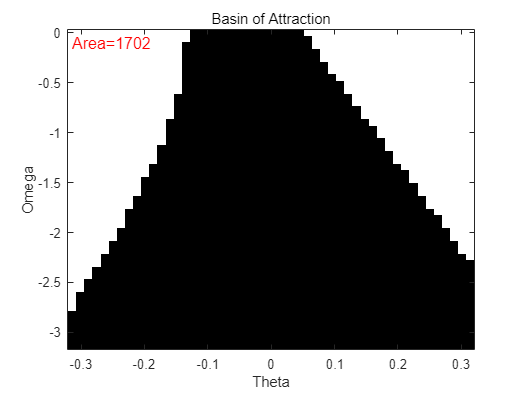


basin(1, 1) = 1;

% 画图
figure;
imagesc(theta_range, omega_range, basin');
xlabel('Theta');
ylabel('Omega');
title('Basin of Attraction');
colormap([1 1 1; 0 0 0]);
set(gca, 'YDir', 'normal');

num_basin_1 = sum(basin(:) == 1);
str = sprintf('Area=%d', num_basin_1);

% 使用 text 函数将信息添加到图上的指定位置
text(min(theta_range), max(omega_range), str, 'VerticalAlignment', 'top', 'HorizontalAlignment', 'left', 'Color', 'r', 'FontSize', 12);
exportgraphics(gca, sprintf('%d-%d-%d-%d.png', slopeAngle, Nspk, Nwt, num_basin_1));

function is_lc = is_limit_cycle(data)
    % 设置阈值，用于判断状态是否足够接近以被认为是在同一个周期轨迹上
    
    
    % 获取状态数据的大小
    data.s = data.s(1:end-20,:);
    data.t = data.t(1:end-20,:);
    [num_steps, num_states] = size(data.s);
    is_lc = 0;
    if num_steps < 3000
        return
    end
    threshold = 5e-3 * sqrt(num_steps / 3000);
    % 默认假设没有找到极限环
    
    
    % 从最后一个状态开始，与之前的所有状态进行比较
    for i = num_steps-1:-1:int32(num_steps * 0.7)
        % 计算范数
        norm_value = norm(data.s(end, :) - data.s(i, :));
        
        % 如果范数小于阈值，则认为找到了极限环
        if norm_value < threshold
            delta_t = data.t(end) - data.t(i);
            if delta_t > 0.01
                next_t = data.t(i) - delta_t;
                [~, idx] = min(abs(data.t - next_t));
                norm_value_2 = norm(data.s(end, :) - data.s(idx, :));
                % fprintf('delta t %f, idx %d.\n', delta_t, idx);
                if norm_value_2 < threshold
                    next_t = data.t(idx) - delta_t;
                    [~, idx] = min(abs(data.t - next_t));
                    norm_value_3 = norm(data.s(end, :) - data.s(idx, :));
                    if norm_value_3 < threshold
                        is_lc = 1;
                        break;
                    end
                    % fprin('Limit cycle detected: state at step %d is close to state at step %d\n', i, num_steps);
                end
            end
        end
    end
end

